# Activity 3

# Model a Multipath Channel

In this activity, you'll add a multipath channel to your simulation. The multipath channel precedes the AWGN because the multipath is encountered in the air, before the signal reaches the receiver that adds the AWGN.

For simplicity, you'll simulate a static channel. However, in scenarios where the transmitter, receiver, or reflectors are moving, the channel impulse response is time varying.

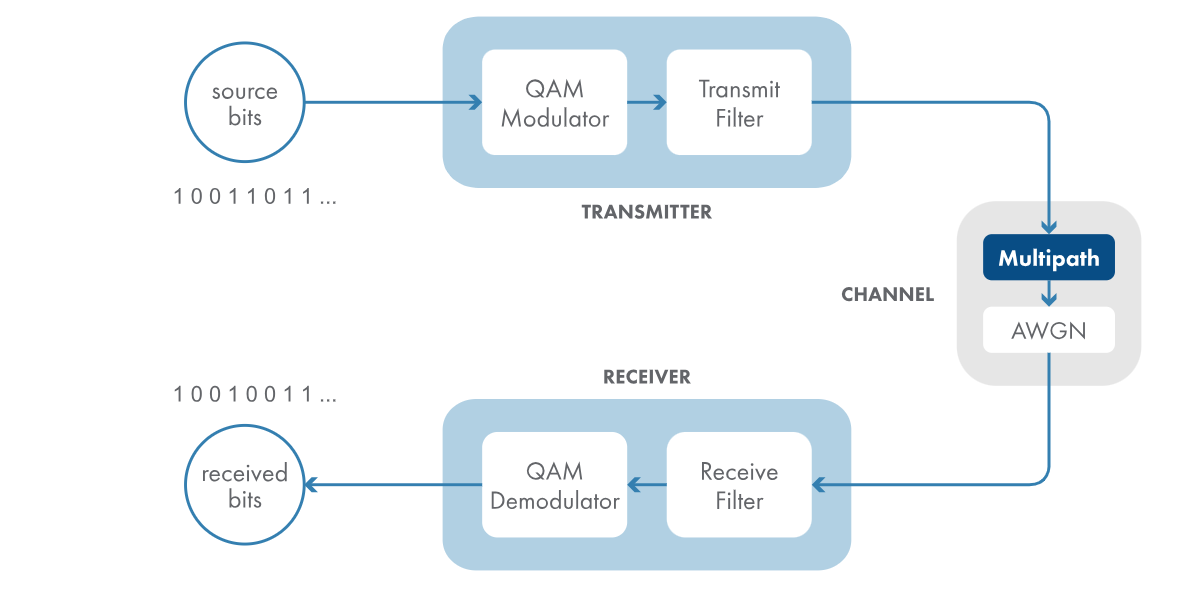

numBits = 20000;
modOrder = 16;  % for 16-QAM
bitsPerSymbol = log2(modOrder);  % modOrder = 2^bitsPerSymbol
txFilt = comm.RaisedCosineTransmitFilter;
rxFilt = comm.RaisedCosineReceiveFilter;

srcBits = randi([0,1],numBits,1);
modOut = qammod(srcBits,modOrder,"InputType","bit","UnitAveragePower",true);
txFiltOut = txFilt(modOut);

**Background**

You can represent a multipath channel as a finite impulse response (FIR) filter. In MATLAB, an FIR filter can be defined by a vector of coefficients.

`b` `=` `[``b0` `b1` `...` `bN``]`

For a multipath channel, you can think of each nonzero coefficient as representing one path and each vector element (after the first) as a delay of one sample.

`mp` `=` `[``p1` `0` `0` `p2` `0` `0` `p3``]`

Since your signals are column vectors, it's good practice to be consistent and make the coefficient vector also a column vector. Transpose a row vector to make it a column vector.

`mp` `=` `[``p1` `0` `0` `p2` `0` `0` `p3``]``.``'`

**TASK**

Create a column vector named `mpChan` with 17 elements. Set the values of the 1st, 9th, and 17th elements to 0.8, -0.5, and 0.34, respectively. All other elements should be 0.

spacing = zeros(7,1);
mpChan = [0.8; spacing; -0.5; spacing; 0.34]

mpChan =     0.8000
         0
         0
         0
         0
         0
         0
         0
   -0.5000
         0


You can visualize the impulse response of your multipath channel as a stem plot using the `stem` function.

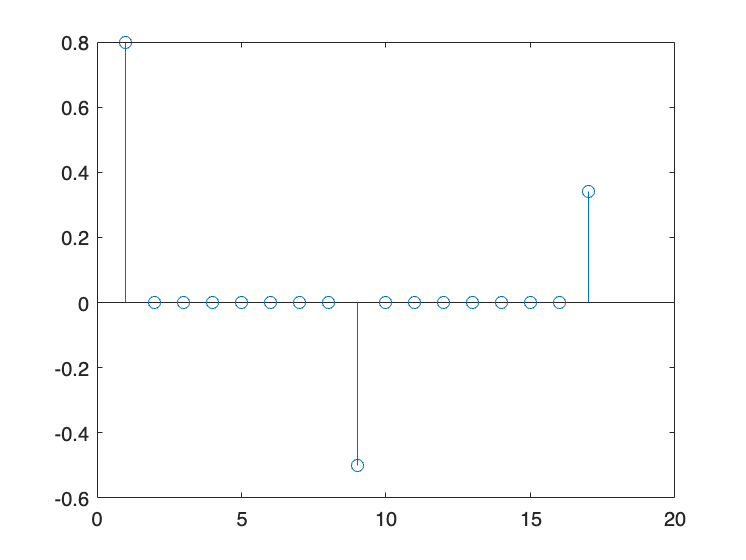

figure;
stem(mpChan)

To apply the FIR filter to a signal, use the `filter` function. The first input is the impulse response, or the numerator coefficients of the filter. The second input is the denominator coefficients—for an FIR filter, this is always `1`. The third input is the signal that you want to filter.

`sigOut` `=` `filter``(``mp``,``1``,``sig``)`

mpChanOut = filter(mpChan,1,txFiltOut)

mpChanOut =   -0.0046 + 0.0046i
  -0.0039 + 0.0039i
  -0.0022 + 0.0022i
   0.0003 - 0.0003i
   0.0033 - 0.0033i
   0.0060 - 0.0060i
   0.0080 - 0.0080i
   0.0085 - 0.0085i
   0.0087 - 0.0147i
   0.0055 - 0.0107i


The following code is executed after the variable `mpChanOut` is created.

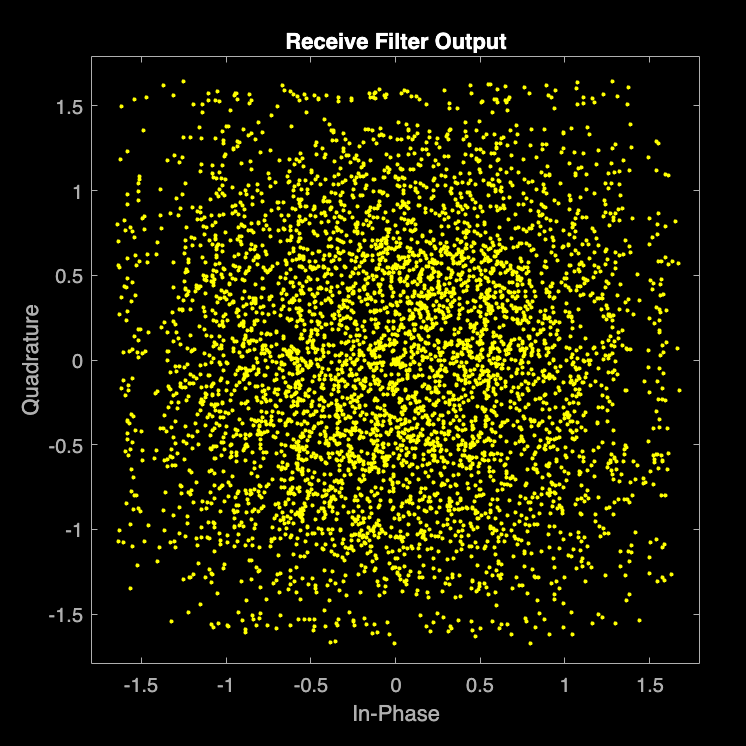

numBitErrors = 4757

BER = 0.2383

if exist("mpChanOut","var")  % code runs after you complete Task 3

    SNR = 15;  % dB
    chanOut = awgn(mpChanOut,SNR,"measured");

    rxFiltOut = rxFilt(chanOut);
    scatterplot(rxFiltOut)
    title("Receive Filter Output")
    demodOut = qamdemod(rxFiltOut,modOrder,"OutputType","bit","UnitAveragePower",true);

    % Calculate the BER
    delayInSymbols = txFilt.FilterSpanInSymbols/2 + rxFilt.FilterSpanInSymbols/2;
    delayInBits = delayInSymbols * bitsPerSymbol;
    srcAligned = srcBits(1:(end-delayInBits));
    demodAligned = demodOut((delayInBits+1):end);

    numBitErrors = nnz(srcAligned~=demodAligned)
    BER = numBitErrors/length(srcAligned)
end

## Further Practice

Once you've defined `mpChanOut` in the script, the rest of the simulation executes. The BER is calculated and displayed in the output pane.

As predicted, the link has been rendered almost useless by the multipath.

To better understand the problem, look at the spectra of the transmitted signal and the channel output by uncommenting the code at the end of the script and running the section. The transmitted signal is yellow, and the received signal is blue.

**"The spectrum of the received signal has a "notch" in its passband,** **which significantly distorts a single-carrier waveform.** **The phenomenon is called frequency-selective multipath, because the level of channel attenuation or gain depends on the frequency."**

Modern systems like LTE, WiFi, and 5G have adopted a technique to deal with multipath. It's called orthogonal frequency-division multiplexing (OFDM), and you will look at that next.

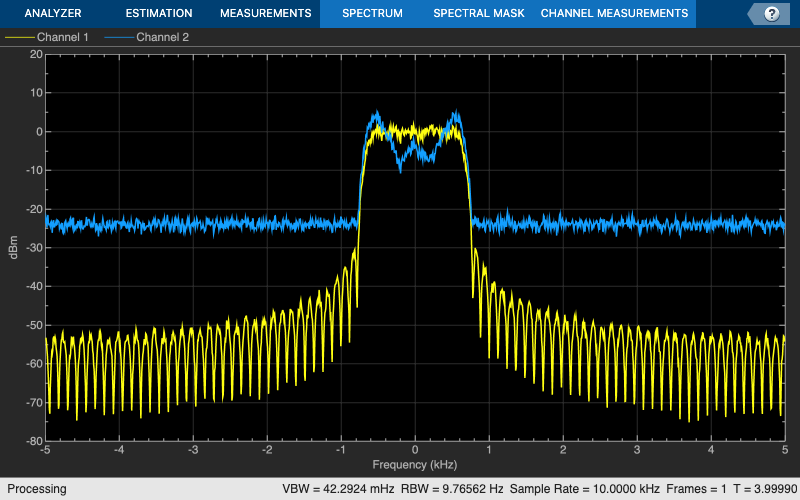

specAn = dsp.SpectrumAnalyzer("NumInputPorts",2, ...
    "SpectralAverages",50,...
    "ShowLegend",true);
specAn(txFiltOut,chanOut)